# Signal Amplitude and Power Feature Group

#### Integrated Absolute Value/ Integrated EMG - IAV/ iEMG

IAV = sum((abs(data_ch1)),2);

#### Waveform Length - Diff of iEMG

WL = sum(abs(diff(data_ch1)),2);

#### Mean Absolute Value - MAV

N = length(data_ch1);
MAV = (sum((abs(data_ch1)),2))/N;

#### Difference Absolute Mean Value - DAMV - Diff of MAV

DAMV = (sum((abs((diff(data_ch1)).^2)),2))/(N-1);

#### Root Mean Square - RMS

RMS = rms(data_ch1,2);

#### Difference Absolute Standard Deviation Value - DASDV - Diff of RMS

DASDV = sqrt((sum(((diff(data_ch1)).^2),2))/N-1);

#### Variance - VAR

VAR = var(data_ch1,0,2);

#### Difference Variance Value - DVARV - Diff of Var

DVARV = (sum(((diff(data_ch1)).^2),2))/(N-2);

#### Mean value of Square Root - MSR

mean(sqrt(data_ch1),2);

#### Log Detector - LD

LD = exp(1/N)*sum(log(data_ch1),2);

# Frequency Information Feature Group

#### Simple Square Integral - SSI

SSI = sum(((data_ch1).^2),2);

#### Second Order Moment - M2 - Diff of SSI

M2 = sum(((diff(data_ch1)).^2),2);

#### Zero Crossing

threshold = 10;  %...we can pick a value here
ZC=0;
for i=1:N-1
  if ((data_ch1(i) > 0 && data_ch1(i+1) < 0) || (data_ch1(i) < 0 && data_ch1(i+1) > 0)) ...
      && (abs(data_ch1(i)-data_ch1(i+1)) >= threshold)
    ZC=ZC+1;
  end
end

#### Slope Sign Change - SSC

threshold = 10 %...we can pick a value here
SSC=0;
for i=2:N-1
  if ((data_ch1(i) > data_ch1(i-1) && data_ch1(i) > data_ch1(i+1)) || (data_ch1(i) < data_ch1(i-1) && data_ch1(i) < data_ch1(i+1))) ...
      && ((abs(data_ch1(i)-data_ch1(i+1)) >= threshold) || (abs(data_ch1(i)-data_ch1(i-1)) >= threshold))
    SSC=SSC+1; 
  end
end

#### Myopulse Percentage Rate - MYOP 

thres = 10; Y=0; 
for i=1:N
  if abs(data_ch1(i)) >= thres
    Y=Y+1;
  end
end
MYOP=Y/N;

#### Willison Amplitude - WAMP - Diff of MYOP - calculates freq of motor unit action potentials

threshold = 10; %...we can pick a value here
N=length(data_ch1); WA=0; 
for k=1:N-1
    if abs(diff(data_ch1)) >= threshold
        WA=WA+1; 
    end
end

#### Median Frequency - MDF

MDF = medfreq(data_ch1(:,1));

#### Mean Frequency - MNF

MNF = meanfreq(data_ch1(:,1));

# Nonlinear Complexity Feature Group 

#### Maximum Fractal Length - MFL - Determines strength of contraction

MFL = log10(sqrt(sum((diff(data_ch1(:,1))).^2)));

#### Detrended Fluctuation Analysis - DFA - Determines self affinity of a signal

DFA = sqrt((1/N)*(sum((diff(data_ch1(:,1))).^2)));

# Time Series Modelling Feature Group

Coefficients of time-varying linear predictive models

#### Autoregressive Coefficients - AR

AR = arburg(data_ch1(:,1),10); 
%where 10 is the model order which must be one less than the length of the array

#### Cepstrum Coefficients - CC

CC = cceps(data_ch1(:,1));

# Unique Feature Group

#### Histogram - HIST

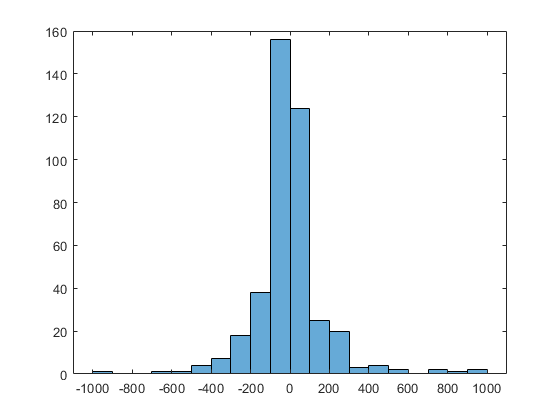

HIST =   Histogram with properties:

             Data: [409×1 single]
           Values: [1 0 0 1 1 4 7 18 38 156 124 25 20 3 4 2 0 2 1 2]
          NumBins: 20
         BinEdges: [-1000 -900 -800 -700 -600 -500 -400 -300 -200 -100 0 100 200 300 400 500 600 700 800 900 1000]
         BinWidth: 100
        BinLimits: [-1000 1000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


threshold = 10

HIST = histogram(data_ch1(:,1));